% import data, zero time, and trim data to relevant amount
data = importdata('Sensor_Motor_Data.txt')

data =         8556          25          25         679         650
        8581          25          25         761         650
        8606         -25          25         872         650
        8632         -25          25         887         646
        8658         -25          25         886         653
        8684         -25          25         884         643
        8710         -25          25         866         636
        8736          25          25         751         639
        8761          25          25         672         633
        8786          25          25         696         635


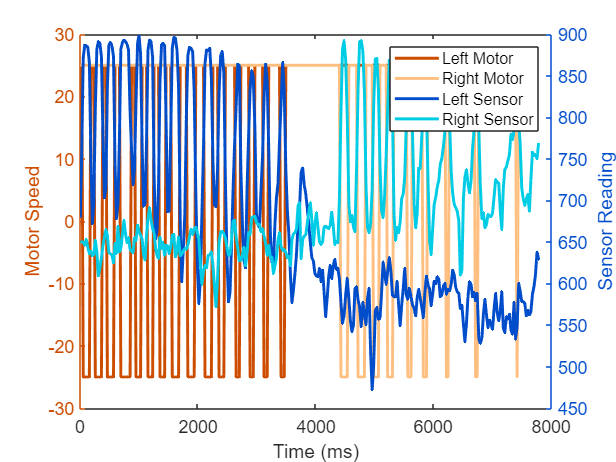

data(:,1) = data(:,1) - 8556;
data([300:end],:)=[];

% define columns of data array
time = data(:, 1);
left_speed = data(:, 2);
right_speed = data(:, 3);
left_sensor = data(:, 4);
right_sensor = data(:, 5);

% set parameters for figure
fig = figure;
left_color = [0.8 0.3 0];
right_color = [0 0.3 0.8];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);
set(gca,'fontsize', 12) 

% plot motor speeds and style lines
yyaxis left
plot(time, left_speed, "Marker", "none", "LineWidth", 2)
hold on
plot(time, right_speed, "Marker", "none",  "Color", [1 0.75 0.5], "LineStyle", "-", "LineWidth", 2)
hold on
xlabel("Time (ms)")
ylabel("Motor Speed")

% plot sensor values and style lines
yyaxis right
plot(time, left_sensor, "Marker", "none", "LineWidth", 2)
hold on
plot(time, right_sensor, "Marker", "none", "Color", [0 0.8 0.9], "LineStyle", "-", "LineWidth", 2)
hold on
ylabel("Sensor Reading")
legend("Left Motor", "Right Motor", "Left Sensor", "Right Sensor")